# LAB 1 - Your Name - MAT 275

# Exercise 1

***NOTE: ****Please suppress output - i.e., use a semicolon ';' at the end of any commands for which the output is not necessary to answer the question. Delete these notes before turning in.*

Define input variable theta as discretized row vector (i.e. array)

theta = [0,pi/5,pi/3,pi/2,(3*pi)/2,(4*pi)/3,(5*pi)/4];

Define radius

r=4;

Define x and y in terms of theta and r

x= r*cos(theta);
y= r*sin(theta);
r_comp = sqrt(x.^2+y.^2);

Check that x and y satisfy the equation of a circle

**Explain results here.** Do x and y satisfy the equation of a circle? Why or why not?

yes x and y staisfy the equation of a circle because the computed radius(r_comp) with the radius of 4 is the same throughout

How does the vector output at the end confirm your answer?

the answers are the same which satisfies the equation

# Exercise 2

Define t-vector

t= linspace(2,10,(10-2)/0.1 + 1);

Define y-vector

y= exp(t / 15).* cos(2*t) ./ (.7*t.^(3)+8);

### Part (a)

Plot results (should have 3 plots total)

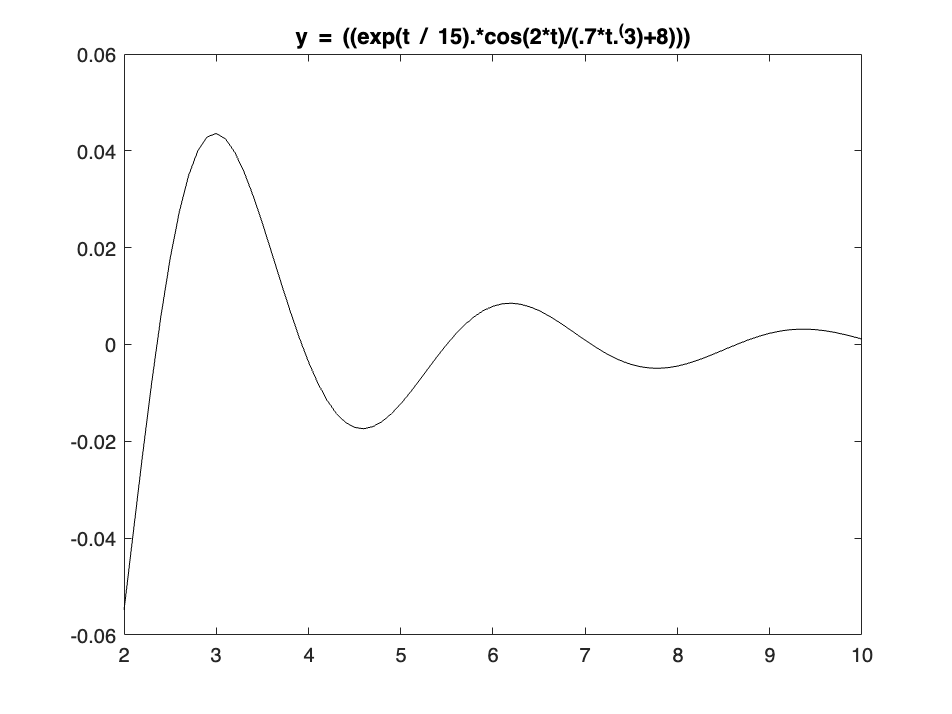

figure;
plot(t, y,'k');
title('y = ((exp(t / 15).*cos(2*t)/(.7*t.^(3)+8)))');

### Part (b)

Plot results as data points only and as data points with line.

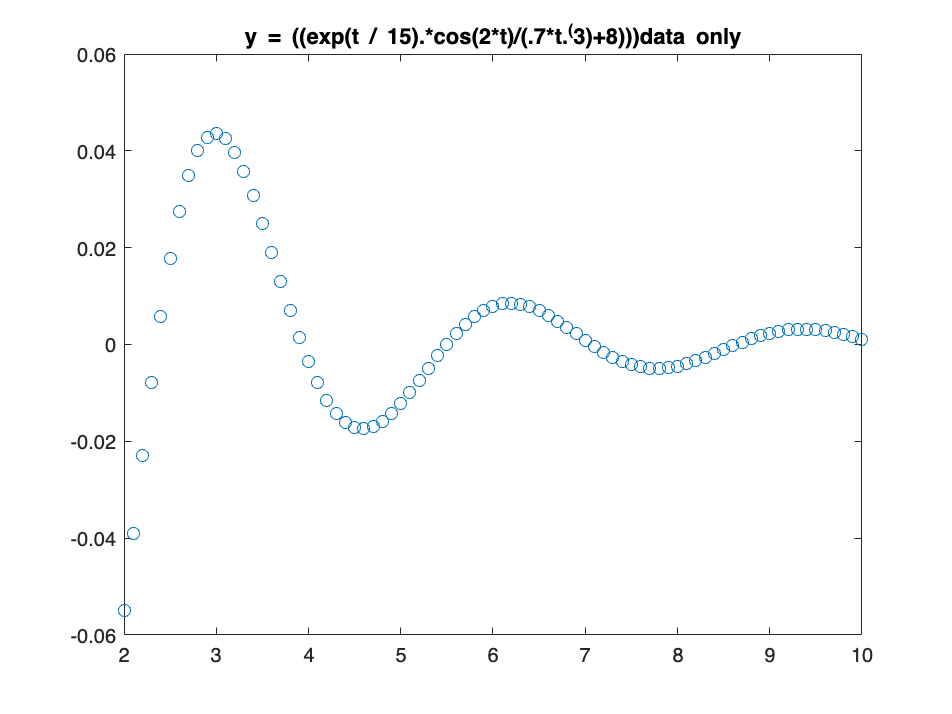

figure %creates another figure window
plot(t,y,'o');
title('y = ((exp(t / 15).*cos(2*t)/(.7*t.^(3)+8)))data only')

# Exercise 3

Create t-vector (choose enough elements so that plot is smooth!)

t = linspace(0,15,1000)

t =          0    0.0150    0.0300    0.0450    0.0601    0.0751    0.0901    0.1051    0.1201    0.1351    0.1502    0.1652    0.1802    0.1952    0.2102    0.2252    0.2402    0.2553    0.2703    0.2853    0.3003    0.3153    0.3303    0.3453    0.3604    0.3754    0.3904    0.4054    0.4204    0.4354    0.4505    0.4655    0.4805    0.4955    0.5105    0.5255    0.5405    0.5556    0.5706    0.5856    0.6006    0.6156    0.6306    0.6456    0.6607    0.6757    0.6907    0.7057    0.7207    0.7357


Define x, y, x components in terms of t

x = 9*cos(3*t); 
y = 9*sin(3*t);
z = 7*t;

Plot results

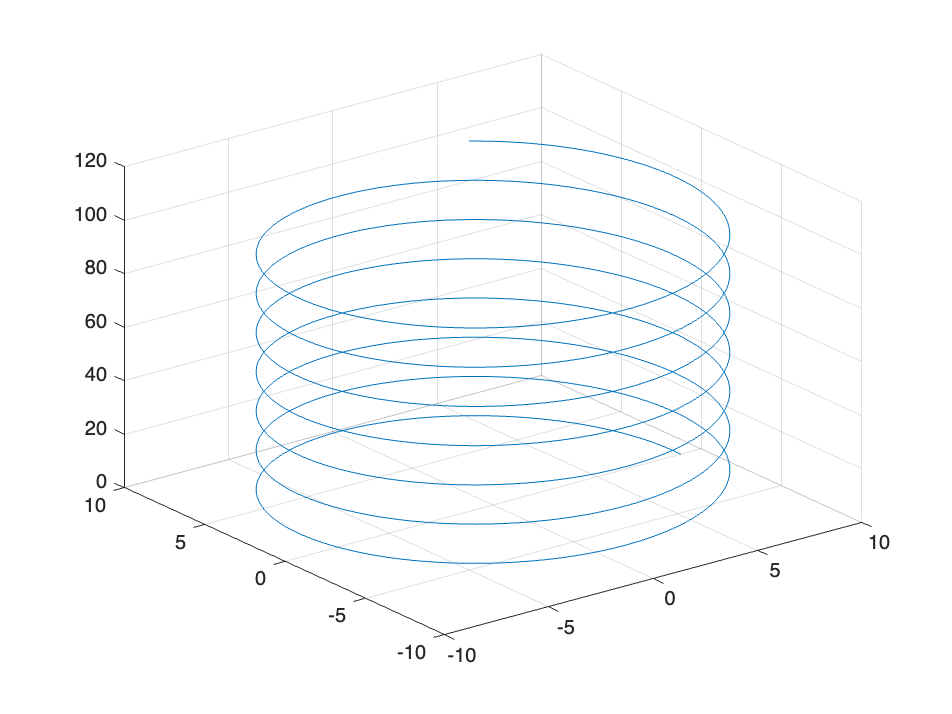

figure;
plot3(x,y,z);
grid on;

***NOTE:**** if graph does not look smooth use more elements in your t-vector -- i.e. use smaller stepsize between elements. Delete these notes before submission.*

# Exercise 4

Define input variable as vector

x= linspace(-pi/2,pi/2,1000);

Define y and z

y = sin(2*x);
z =2*x-(4/3)*x.^(3);

Plot results

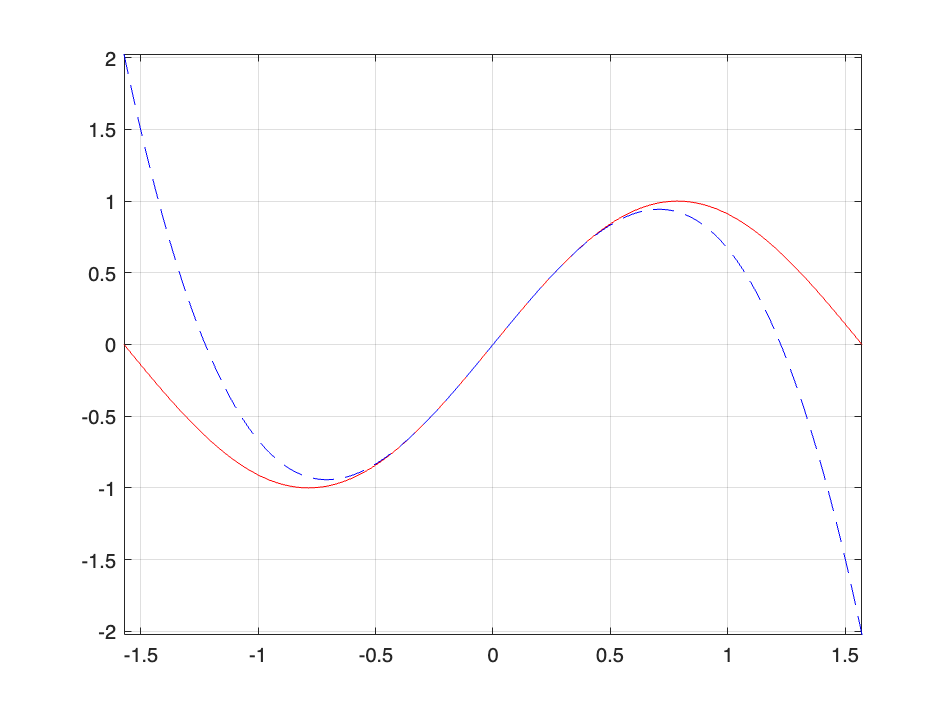

figure;
plot(x,y,'r',x,z,'b--')
axis tight;
grid on

# Exercise 5

**NOTE:*** you must create the M-file ex5.m separately and invoke it here in your livescript file. Delete these notes before submission.*

type ex5.m

x = linspace(0,9,1000) ; % define the vector x in the interval [0,9]
y1 = f(x,170); % compute the 
y2 = f(x,280); % compute the 
y3 = f(x,420); % compute the 
plot(x,y1,'b-','LineWidth',2)
hold on 
plot(x,y2,'r--','LineWidth',2)
plot(x,y3,'g-','LineWidth',2)% plot the three 
hold off
title ('Solutions to dy/dx = −3x + 4x2 − 14 cos(x)') % add a title 
legend ('C=170','C=280','C=420','Location','best') % add a legend

function y = f(x,C)
y = -(3/2)*(x.^2)+(4/3)*(x.^3)-14*sin(x)+C; % fill-in with the 
end


importdata ex5.m

ans = 14×1 cell array
    {'x = linspace(0,9,1000) ; % define the vector x in the interval [0,9]'}
    {'y1 = f(x,170); % compute the '                                       }
    {'y2 = f(x,280); % compute the '                                       }
    {'y3 = f(x,420); % compute the '                                       }
    {'plot(x,y1,'b-','LineWidth',2)'                                       }
    {'hold on '                                                            }
    {'plot(x,y2,'r--','LineWidth',2)'                                      }
    {'plot(x,y3,'g-','LineWidth',2)% plot the three '                      }
    {'hold off'                                                            }
    {'title ('Solutions to dy/dx = −3x + 4x2 − 14 cos(x)') % add a title ' }
    {'legend ('C=170','C=280','C=420','Location','best') % add a legend'   }
    {'function y = f(x,C)'                                                 }
    {'y = -(3/2)*(x.^2)+(4/3)*(x.^3)-14*sin(x)+C; % fi

Run your M-file--i.e. execute the M-file

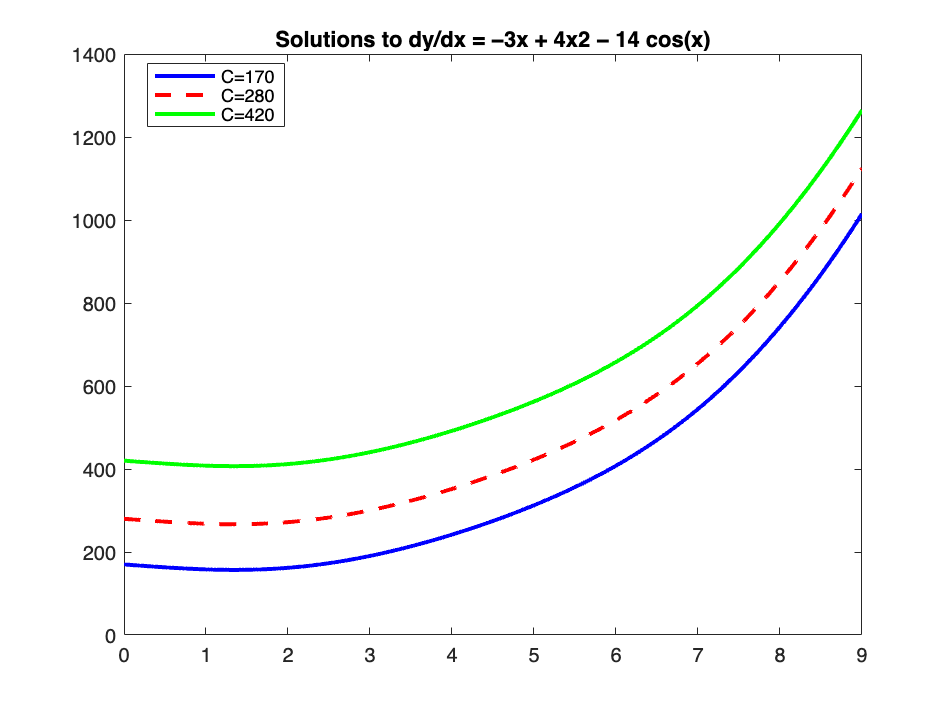

run 'ex5.m'

# Exercise 6

### Part (a)

Define g as anonymous function

g=@(x,y)(((x.^4)/(y.^5)+cos(2*x*exp(9*y))/((x.^7)+4)));

Evaluate g at the given values of x and y

result = g(6,-7);

### Part (b)

***NOTE****: You need to create a separate M-file (g.m) and invoke it in the main file, here. Erase these notes upon submission.*

Clear the function g out of the workspace

clear g

Print out g.m contents

type 'g.m'

function output = g(x,y)
output= (g = @(x,y)(((x.^4)/(y.^5)+cos(2*x*exp(9*y))/((x.^7)+4)));
end


Evaluate g at the given values of x and y

result = g(6,-7);

Error: File: g.m Line: 2 Column: 12
Unsupported use of the '=' operator. To compare values for equality, use '=='. To specify name-value arguments, check that name is a valid identifier with no surrounding quotes.

The End!!!